# Correct Image for Lens Distortion

Create a set of calibration images.

images = imageDatastore("/home/nscl2004/fisheye_cali/img_eo", "FileExtensions", ".png")

images =   ImageDatastore with properties:

                       Files: {
                              '/home/nscl2004/fisheye_cali/img_eo/1.png';
                              '/home/nscl2004/fisheye_cali/img_eo/10.png';
                              '/home/nscl2004/fisheye_cali/img_eo/11.png'
                               ... and 34 more
                              }
                     Folders: {
                              '/home/nscl2004/fisheye_cali/img_eo'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


Detect calibration pattern.

[imagePoints,boardSize] = detectCheckerboardPoints(images.Files);

Generate world coordinates of the corners of the squares. The square size is in millimeters.

squareSize = 29;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

Calibrate the camera.

I = readimage(images,1); 
imageSize = [size(I,1),size(I,2)];
cameraParams = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

Remove lens distortion and display results.

images_eval = imageDatastore("/home/nscl2004/fisheye_cali/image_eo_eval", "FileExtensions", ".png")

images_eval =   ImageDatastore with properties:

                       Files: {
                              '/home/nscl2004/fisheye_cali/image_eo_eval/38.png'
                              }
                     Folders: {
                              '/home/nscl2004/fisheye_cali/image_eo_eval'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



I = images_eval.readimage(1);

J1 = undistortImage(I,cameraParams);

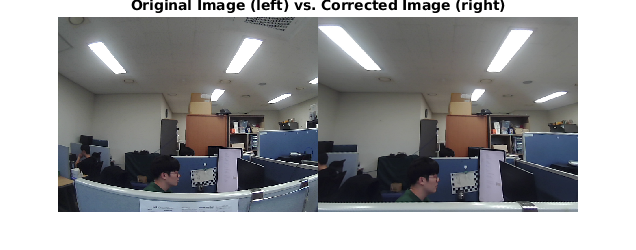

figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)');

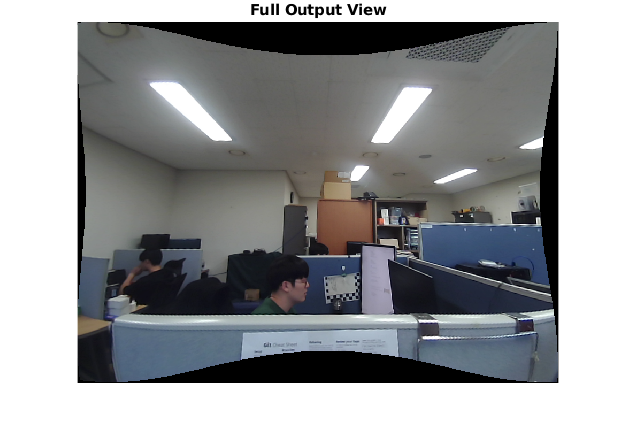

J2 = undistortImage(I,cameraParams,'OutputView','full');
figure; 
imshow(J2);
title('Full Output View');

[intrinsicMatrix,distortionCoefficients] = cameraIntrinsicsToOpenCV(cameraParams);

*Copyright 2012 The MathWorks, Inc.*